**Simulazione Risposta ad una funzione a gradino**

Si vuole capire l'andamento dei dati misurati:

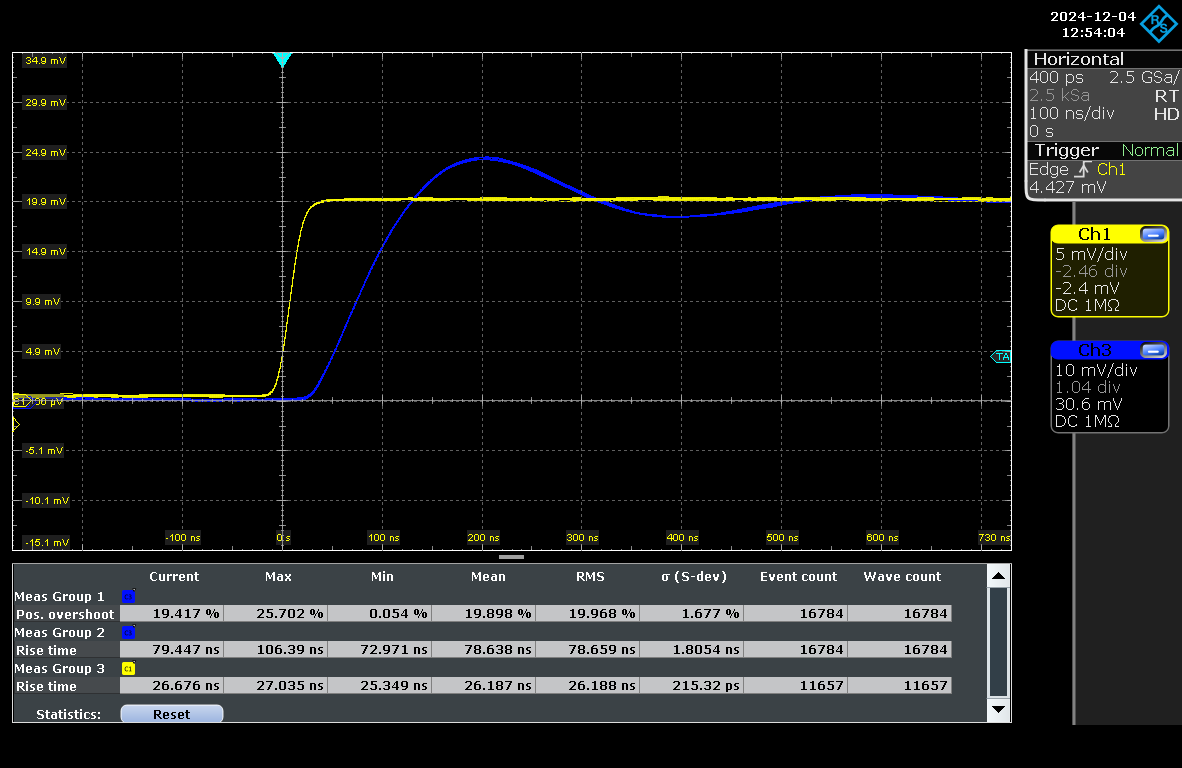

L'operazionale in questione è il OP27 che risulta essere un amplificatore a singolo polo dominante.

In questo file vogliamo comprendere l'andamento di overshoot.

**Singolo Polo Dominante**

Se consideriamo l'amplificatore non ideale con un singolo polo dominante:


$$A\left(s\right)=\frac{A_0 }{1+s\;\tau_A }$$


La risposta del circuito con singolo polo dominante risulta proporzionale alla seguente:

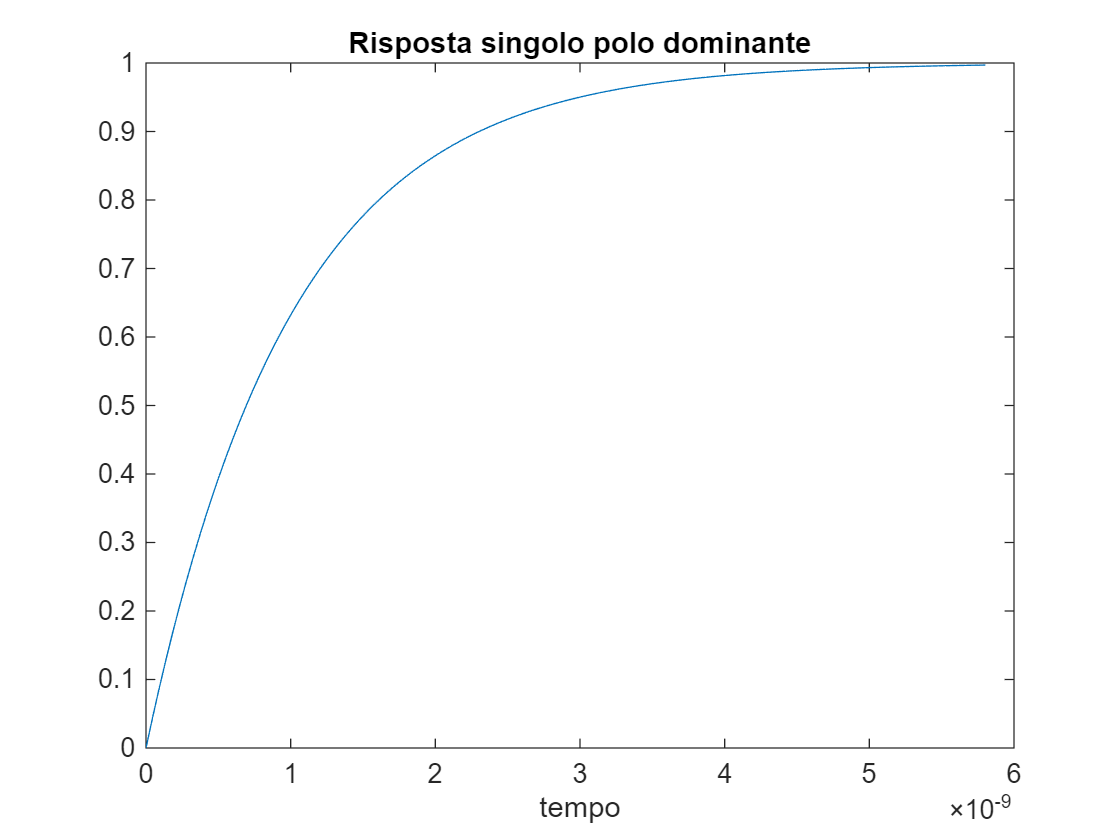

A_o = 1;
tau_a = 1e-9;
sys = tf([A_o], [tau_a, 1]);

[y, tOut] = step(sys);
f = figure(1);
plot(tOut, y)
title('Risposta singolo polo dominante')
xlabel('tempo')

E' evidente che in un circuito a singolo polo non è possibile ottenere overshoot.

**Capacità Parassite**

Per comprendere le misurazioni è necessario considerare la presenza di capacità parassite parallele alle resistenze.

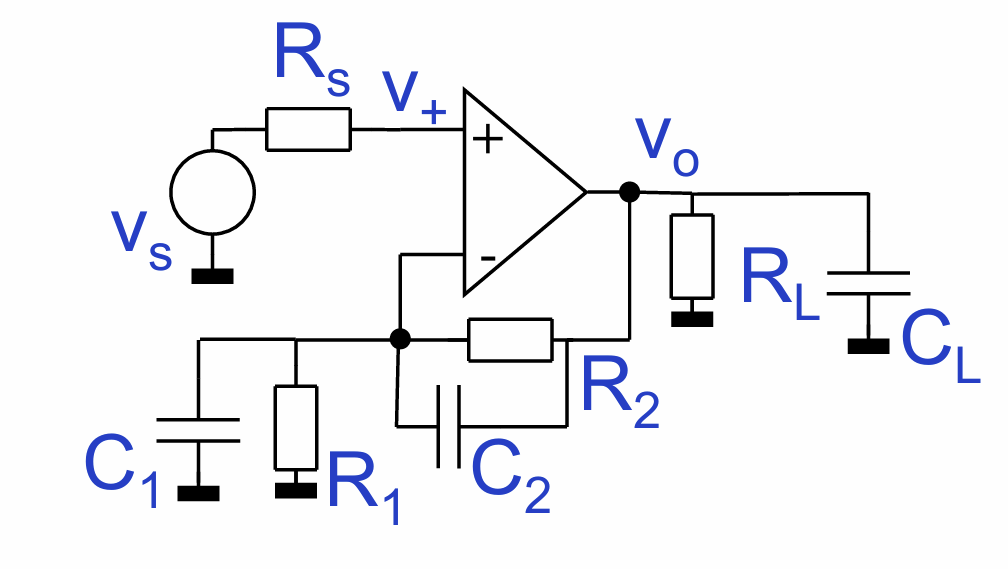

Si ottiene infatti una funzione di trasferimento della tipologia (presa dal pdf delle lezioni al [link](https://pessina.mib.infn.it/Corsi_del_III_anno/CorsoStrumentazioneElettronica/Corso_2425/Amplificatori_reazionati_analisi_tempo_frequenza_B_2425.pdf)):


$$T\left(s\right)=\frac{R_1 }{R_1 +R_2 }\frac{1+{\textrm{sC}}_2 R_2 }{1+s\left(C_1 +C_2 \right)\left(\frac{R_1 R_2 }{R_1 +R_2 }\right)}\;A\left(s\right)$$


inserendo A(s) e impostando $\tau_{1=\;} \left(C_1 +C_2 \right)\left(\frac{R_1 R_2 }{R_1 +R_2 }\right)$ e $\tau_2 =R_2 C_2$

si ottiene:


$$T\left(s\right)=\frac{R_1 }{R_1 +R_2 }\frac{1+s\tau_2 }{\left(1+s\tau_1 \right)}\frac{1}{\left(1+s\tau_A \right)}$$


da cui si deduce un andamento a polo doppio.

E' possibile vedere ciò nella simulazione seguente:

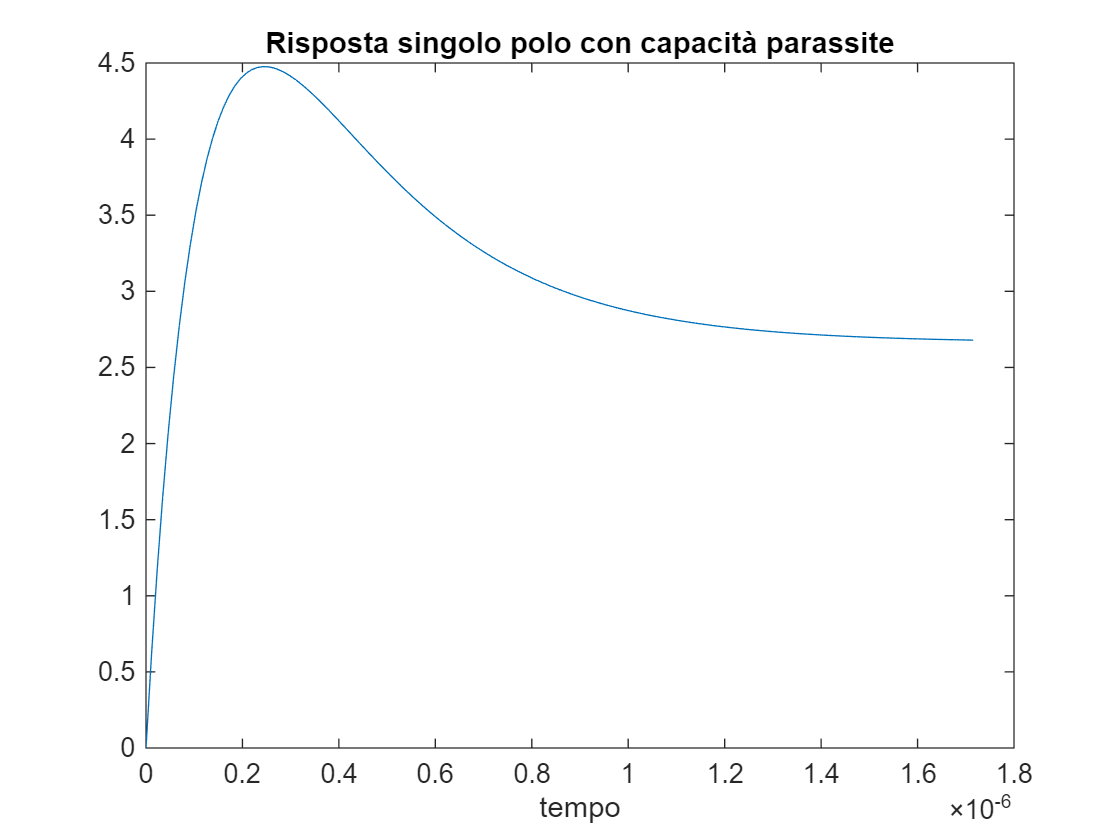

R1 = 2.2e3;
R2 = 3660;
C1 = 1e-20; %Capacità parassite
C2 = 2e-10;

t1 = (C1+C2)*(R1*R2)/(R1+R2); % corrisponde a tau_1
t2 = C2*R2;                   % corrisponde a tau_2
ta = 1/(8e6);                 % suppongo il polo sia a 8Mhz
A_o = (R2+R1)/R1;

gain=1;

num = [t2, 1];
den = [(t1*ta), (t1+ta), 1];

sys = gain * A_o * tf(num, den);

[y, tOut] = step(sys);

figure(2);
plot(tOut, y)
title('Risposta singolo polo con capacità parassite')
xlabel('tempo')